%obj = obj;
vec = obj.getCurrentVec;
fs = obj.fs;
timerange = obj.times;
timeVec = obj.timeVec;
s = obj.stft;
f = obj.cyclicalF;
dt = mean(diff(timeVec));

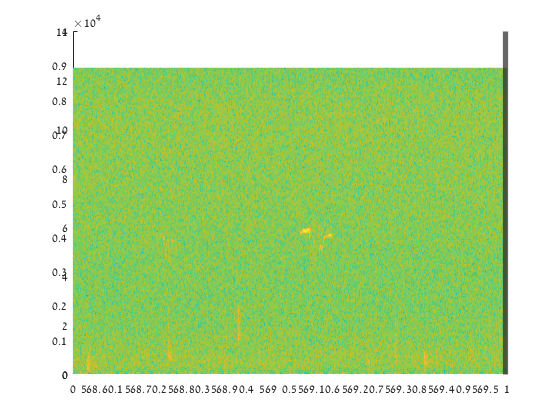

ax = axes;


surface(ax,timeVec,f,s,'EdgeColor','none');
vline = xline(ax,timeVec(1),'','LineWidth',4);
ax.XLim = timerange;

timeVecDown = downsample(timeVec,5);
numSamples = numel(timeVecDown);
fps = round(numSamples/(diff(timerange)*(2.5e5/10000)));

for k = 1:numSamples
    vline.Value = timeVecDown(k);
    frames(k) = getframe(ax) ;   
end

% Create a video player object to play the video file.
videoPlayer = vision.VideoPlayer;
H = dsp.AudioPlayer(10000);
% Use a while loop to read and play the video and audio frames.
while ~isDone(videoFReader)
  [videoFrame,a] = step(videoFReader);
  step(H,a);
  step(videoPlayer, videoFrame);
end
% Release the objects.
release(videoPlayer);
release(videoFReader);